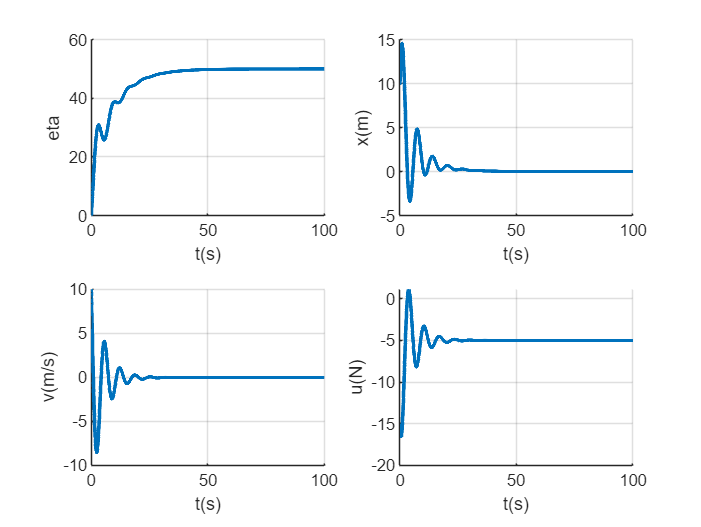

%% 初始设置
close all,clear,clc,
tic,

global m
m = 1;
kp = 1;
kd = 0.5;
ki = 0.1;
f = 5;

t0 = 0;
dt = 0.01;
tf = 100;

% 初始值
x = 10;
v = 10;
state = [x;v];
stateout = state;
uout = [];
tout = t0:dt:tf;
eta = 0;
etaout = eta;
xout = x;
vout = v;

%% 仿真
for t=t0:dt:tf
    u = -kp * x - kd * v - ki * eta;
    uout = [uout, u];
    % 迭代方程组
    ke1 = statequation(t, state, u, f);
    ke2 = statequation(t+0.5*dt, state+0.5*ke1*dt, u, f);
    ke3 = statequation(t+0.5*dt, state+0.5*ke2*dt, u, f);
    ke4 = statequation(t+dt, state+ke3*dt, u, f);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];
    xout = [xout, x];
    vout = [vout, v];

    x = state(1);
    v = state(2);
    eta = eta + x * dt;
    etaout = [etaout, eta];
end
tout = [tout, tf + dt];
uout = [uout, -kp * x - kd * v - ki * eta];

%% 绘图
figure;

subplot(2, 2, 1);
hold on;
grid on;
plot(tout, etaout, 'LineWidth', 2);
ylabel('eta');
xlabel('t(s)');

subplot(2, 2, 2);
hold on;
grid on;
plot(tout, xout, 'LineWidth', 2);
ylabel('x(m)');
xlabel('t(s)');

subplot(2, 2, 3);
hold on;
grid on;
plot(tout, vout, 'LineWidth', 2);
ylabel('v(m/s)');
xlabel('t(s)');

subplot(2, 2, 4);
hold on;
grid on;
plot(tout, uout, 'LineWidth', 2);
ylabel('u(N)');
xlabel('t(s)');


toc,

历时 0.288429 秒。


function output=statequation(t, state, u, f)
global m

x = state(1);
v = state(2);

xdot = v;
vdot = 1 / m * (u + f);

output = [xdot;vdot];
end